# HW 01 - Financial Econometrics

## Details

Author - Davis Vaughan

Date    - 2017-09-01

HW      - 01

*If you have opened the simulink project (.prj) file with Matlab, *

*your MATLABPATH should be set so that the relative references to data and functions "just work".*

## Load data

crsp = xlsread('data/sizeDecileReturns.xls');

% Looks like dates are never actually used, remove them for code readability
date = crsp(:, 1);
crsp = crsp(:, 2:end);

% You say to use percentage returns in all of the examples. Change decimal to percent here
crsp = crsp * 100;

% Short G format is easy to read and actually prints things right
format shortG;

% Seed
rng(1234);

## Problem 1

A)

mean(crsp)

ans =      0.072779     0.055515     0.059556     0.066928     0.073444     0.066704     0.066107     0.059582     0.052707    0.0075381



max(crsp)

ans =        8.1969       3.1555       2.6871       2.8165       3.2541       3.7652       4.8502       5.1655       5.3187       5.5913



min(crsp)

ans =       -5.1477       -4.282      -5.1066      -3.2128      -3.7655      -4.3835      -4.6154      -5.2493      -5.6997      -5.4798


B)

% Largest Decile 1 percentage return
d1 = nan(length(crsp), 2);
[d1(:, 1), d1(:, 2)] = sort(crsp(:, 1), 'descend');
d1(1, :)

ans =        8.1969          641



% Smallest Decile 10 absolute percentage return
d10 = nan(length(crsp), 2);
[d10(:, 1), d10(:, 2)] = sort(abs(crsp(:, 10)));
d10(1, :)

ans =       0.00157         1026


C) 

% This makes sense, corr of those in similar market cap ranges is higher
corr(crsp(:, end), crsp(:, 1:end-1))

ans =       0.48889      0.54885      0.62216      0.73042       0.7573      0.79241      0.84265      0.88099      0.90879


D)

% i) w = 1 means divide by N, which is without bias correction
std(crsp .^ 2, 1)

ans =         2.811      0.92969       1.0644      0.83739       1.1605       1.4418       1.8878       1.9875        2.288       2.7111



% ii) w = 0 means divide by N-1, which is with bias correction
std(crsp .^ 2, 0)

ans =        2.8121      0.93006       1.0648      0.83772        1.161       1.4424       1.8886       1.9882       2.2889       2.7122


% iii) w = 0 means divide by N-1, which is with bias correction, and dim = 2 does rowwise operation
std_bias_rowwise = std(crsp .^ 2, 0, 2);
std_bias_rowwise(1)

ans =        2.2444


E)

Again, if you have opened the simulink project (.prj) then the functions should be visible on the path already. Otherwise they are in the `functions` folder.

normal_log_likelihood(0, 0, 1)

ans =      -0.91894


F)

Kind of tricky here. Can't just compute this directly using `log(prod(normal_pdf(...)))`. Computationally not enough precision so this just goes to -Inf (because the product went to 0). Instead, bring the log inside the product first to change the multiplication to addition.


$$log(\prod_{i=1}^{N} {\frac{1}{\sqrt{2\pi\sigma^2}} e^{-\frac{(x_i - \mu)^2 }{2 \sigma^2}})$$



$$\sum_{i=1}^{N} log({\frac{1}{\sqrt{2\pi\sigma^2}} e^{-\frac{(x_i - \mu)^2 }{2 \sigma^2}})$$


x     = crsp(:, 5);
mu_x  = mean(x);
var_x = var(x);

modified_normal_log_likelihood(x, mu_x, var_x)

ans =       -1479.3


## Problem 2

A)

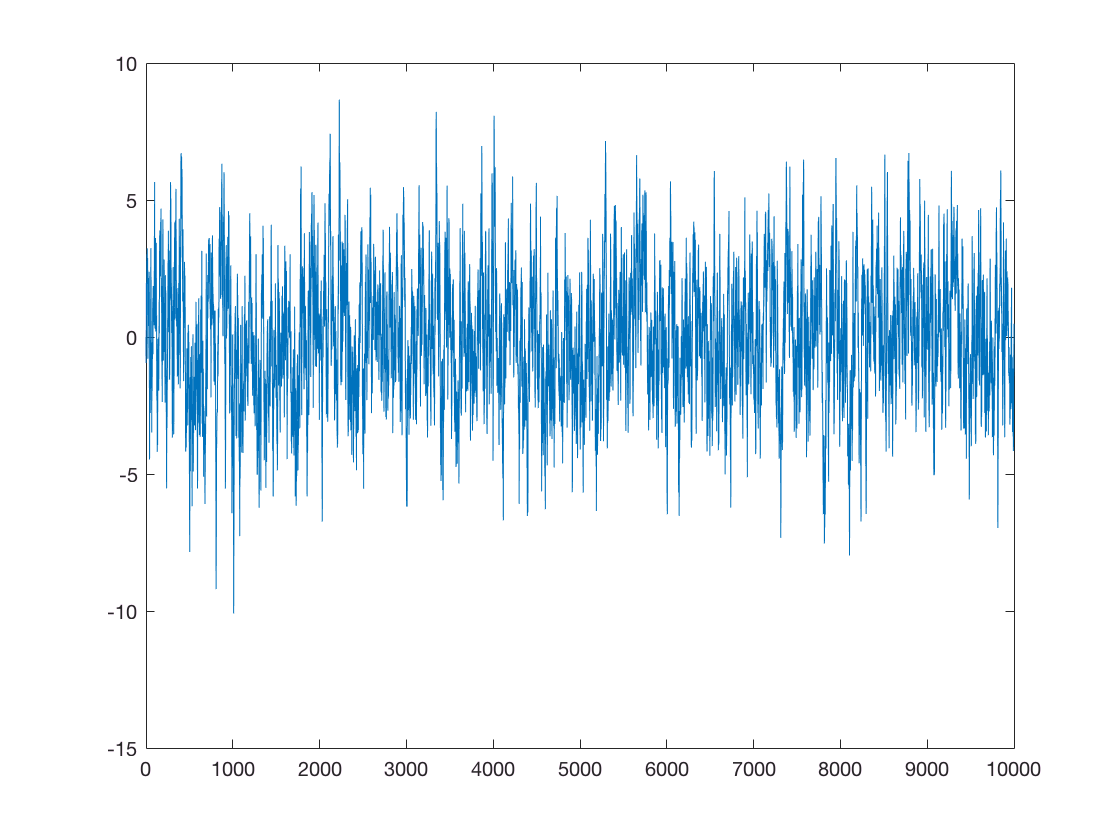

% Params
e     = randn(10000, 1);
Y_a   = zeros(10000, 1);
Y_0   = 0;
alpha = 0.1;

for(i = 1:length(e))   
    
    % Take care of starting case
    if(i == 1) 
        Y_a(i) = (1 - alpha) * Y_0 + e(i);
        continue
    end
    
    Y_a(i) = (1 - alpha) * Y_a(i-1) + e(i);
end

plot(0:length(Y_a), [Y_0; Y_a])

B)

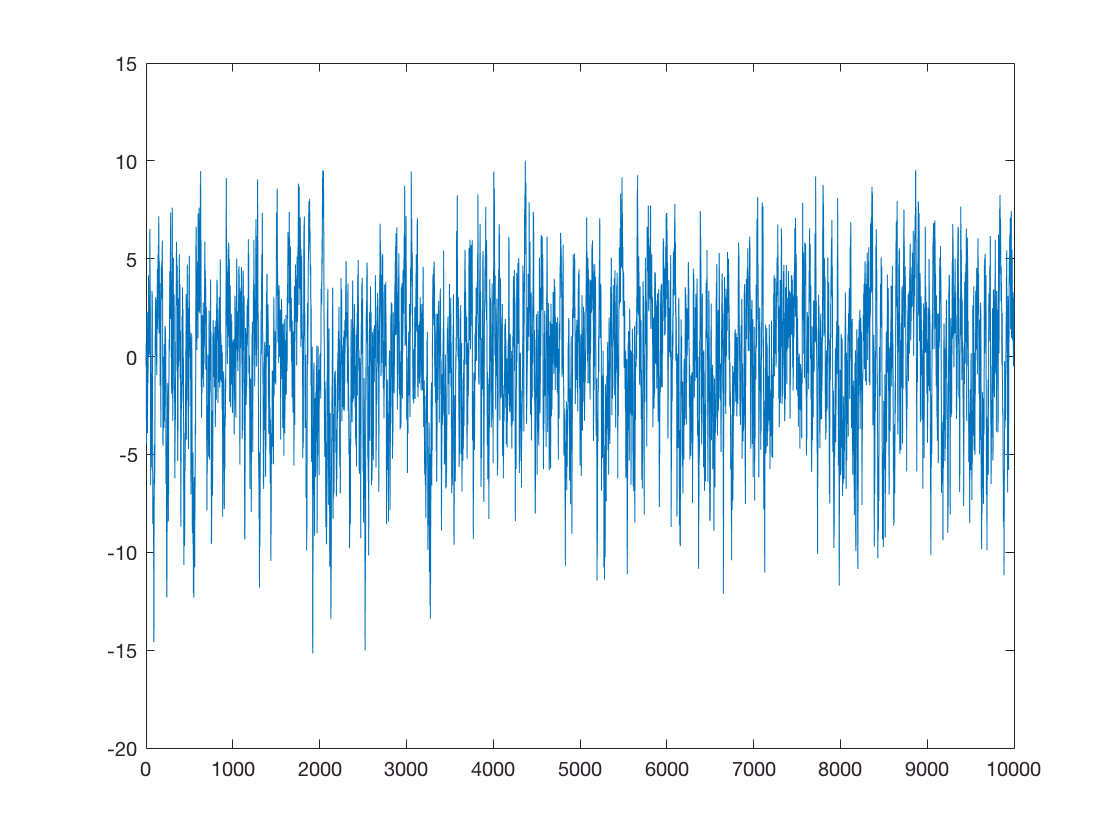

% Params
e     = randn(10000, 1);
Y_b   = zeros(10000, 1);
Y_0   = 0;
e_0   = 0;
alpha = 0.1;

for(i = 1:length(e))   
    
    % Take care of starting case
    if(i == 1) 
        % This stays the same as before because at t = 0, the indicator is 0
        Y_b(i) = (1 - alpha) * Y_0 + e(i);
        continue
    end
    
    % One liner that just uses logicals instead of if statement
    I = double(e(i-1) < 0);
    
    Y_b(i) = (1 - alpha) * Y_b(i-1) + (1 + I) * e(i);
end

plot(0:length(Y_b), [Y_0; Y_b])

C) 

As the length of the time series in a increases, the sample kurtosis should converge to 3, the same as the normal distribution. The reason for this is easy to see if we expand the recusion a bit. For example, consider the first two terms, Y_2 and Y_1.


$$Y\left(2\right)=\left(1-\alpha \right)∗\left(\left(1-\alpha \right)∗Y\left(0\right)+e\left(1\right)\right)+e\left(2\right)$$


The only random pieces here are $e\left(1\right)$and $e\left(2\right)$, both of which are normally distributed. The sum of two independent normal random variables is another normal random variable, so $Y\left(2\right)$ is normally distributed with a kurtosis of 3. Extending this to the general case means that all of $Y\left(t\right)$ is normally distributed with a kurtosis of 3. 

kurtosis(Y_a)

ans =        3.0444


kurtosis(Y_b)

ans =        3.0989


## Problem 3

A)

% Create a var for decile 5 since we use it a lot
crsp_5 = crsp(:, 5);

% # of returns less than 0
sum(crsp_5 < 0)

ans =    552



% # of returns equal to 0
sum(crsp_5 == 0)

ans =      0



% # of returns greater than 0
sum(crsp_5 > 0)

ans =    704


B)

% Number of absolute returns greater than 2x the std
sd_2x = 2 * std(crsp_5, 1);
sum(abs(crsp_5) > sd_2x)

ans =     51


C)

% Which days had negative returns?
neg_rows = find(crsp_5 < 0);
rNeg = crsp_5(neg_rows);

% Average of those negative days
mean(rNeg)

ans =      -0.61055



% Std Dev of those negative days
std(rNeg, 1)

ans =        0.5426


D)

% returns of all deciles in that day >0
sum(all(crsp > 0, 2))

ans =    333



% i) return of at least 1 decile in that day >0
sum(any(crsp > 0, 2))

ans =         1030



% ii) no positive returns in that day
% Just the logical flip of the one before
% sum(all(crsp < 0, 2)) this makes more sense to me
sum(~any(crsp > 0, 2))

ans =    226
